### Removing Electrode Motion Artifacts Using Butterworth Highpass filter

clc;
clear all;
close all;

%Loaded ECG Signal
load('100m.mat')

%Removing the Base and Gain from ECG Signal
ECGsignal_original = (val -1024)/100;
Fs = 360;

%Frequency of PowerLine Interference
L = length(ECGsignal_original);
t = (1:L)/Fs;

%Defining Cutoff Frequency and order 
fc = 5;
N = 2;
[b,a] = butter(N,fc/(Fs/2),'high');
t1 = tf(b,a,1/Fs)

t1 =
 
  0.9402 z^2 - 1.88 z + 0.9402
  ----------------------------
     z^2 - 1.877 z + 0.8839
 
Sample time: 0.0027778 seconds
Discrete-time transfer function.
Model Properties


[z,p,k] = tf2zp(b,a)

z =      1
     1


p =    0.9384 + 0.0581i
   0.9384 - 0.0581i


k = 0.9402

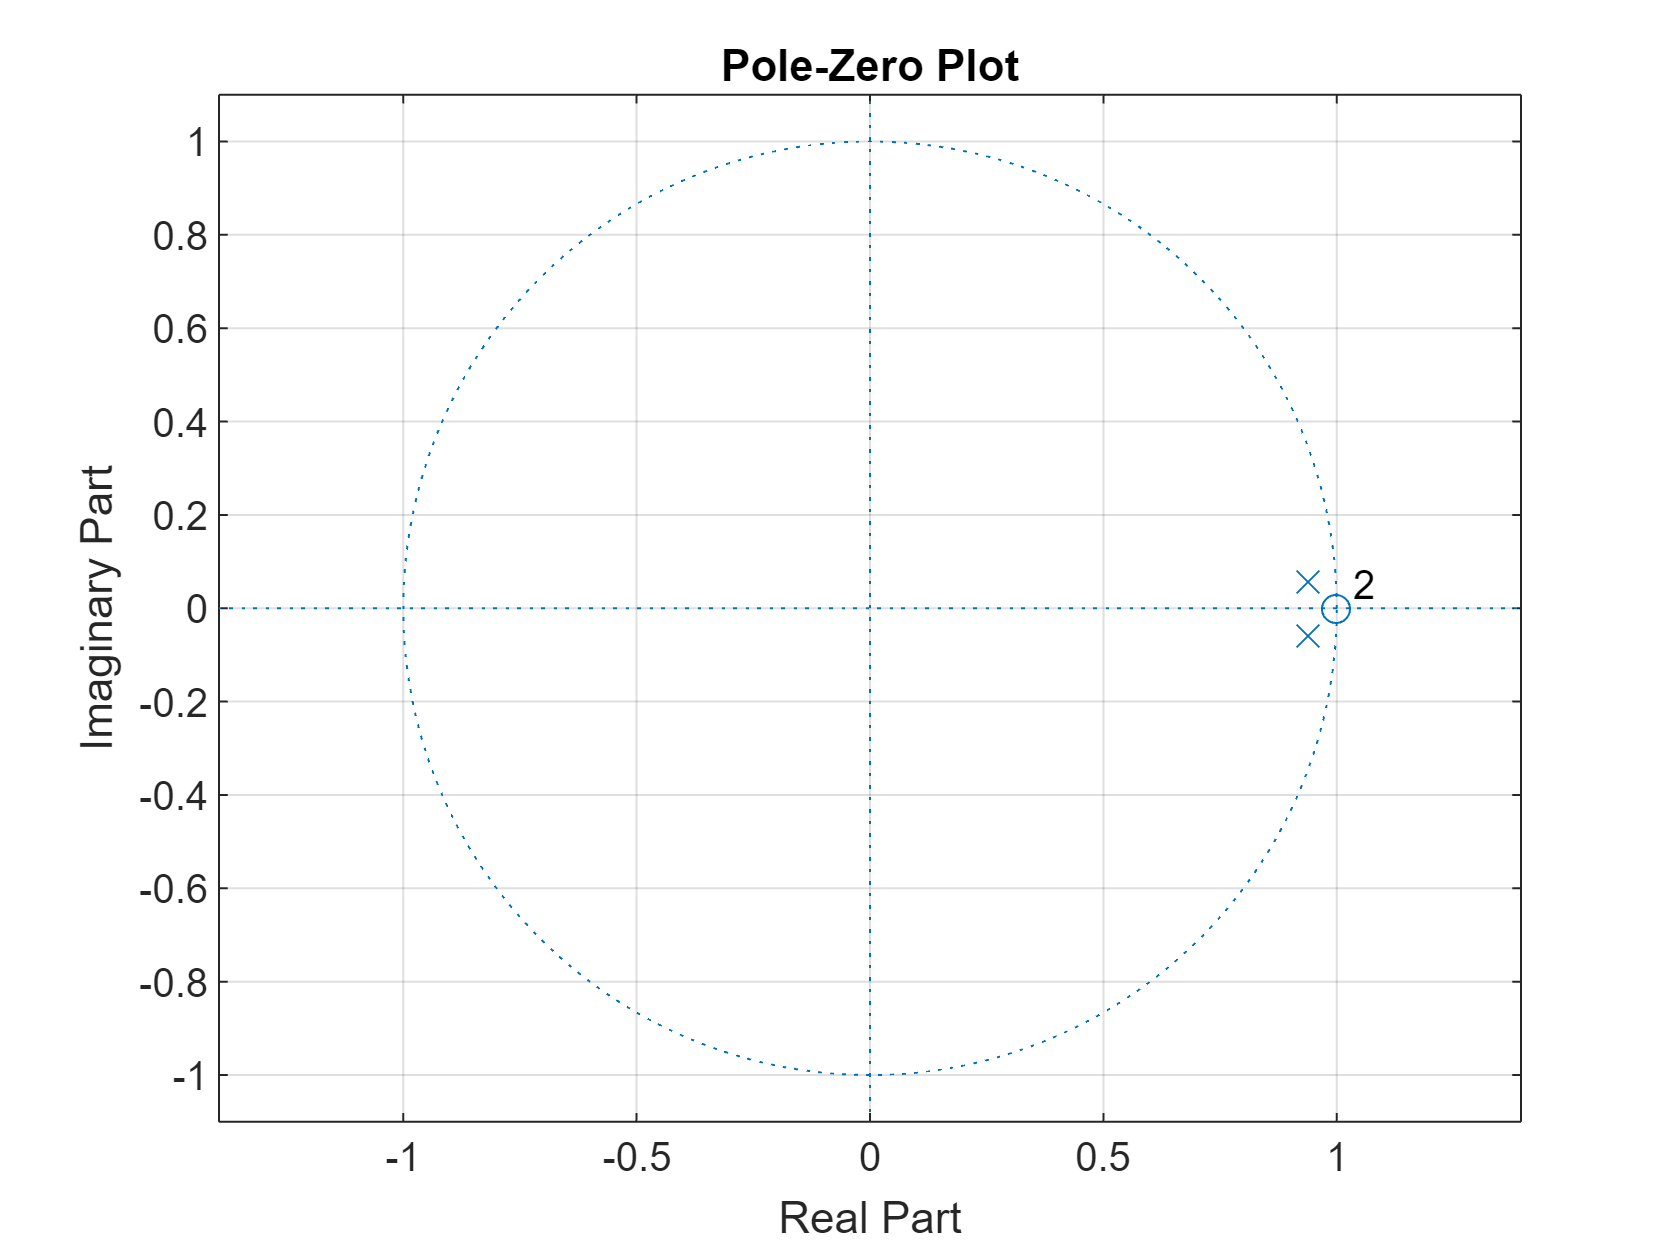

zplane(z,p,k)
grid on

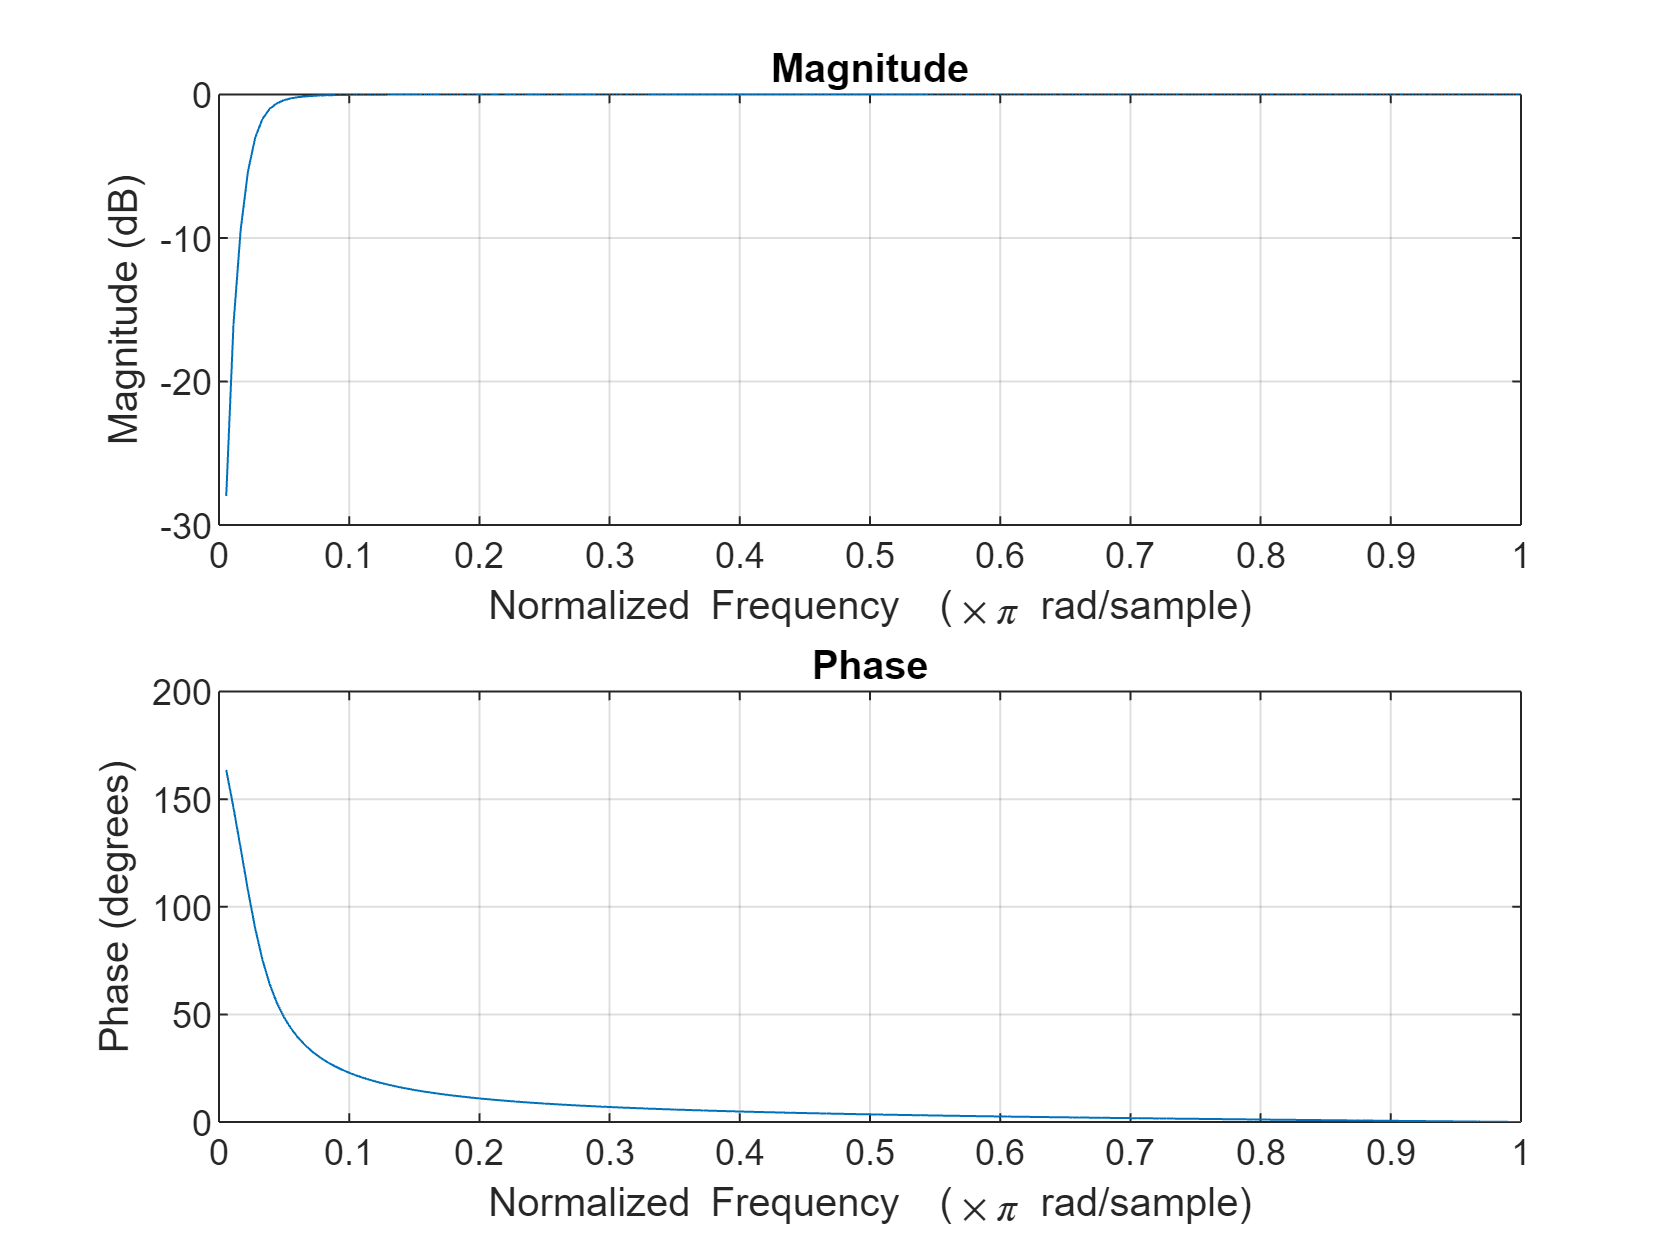

w = 0:2*pi/Fs:pi;
freqz(b,a,w)

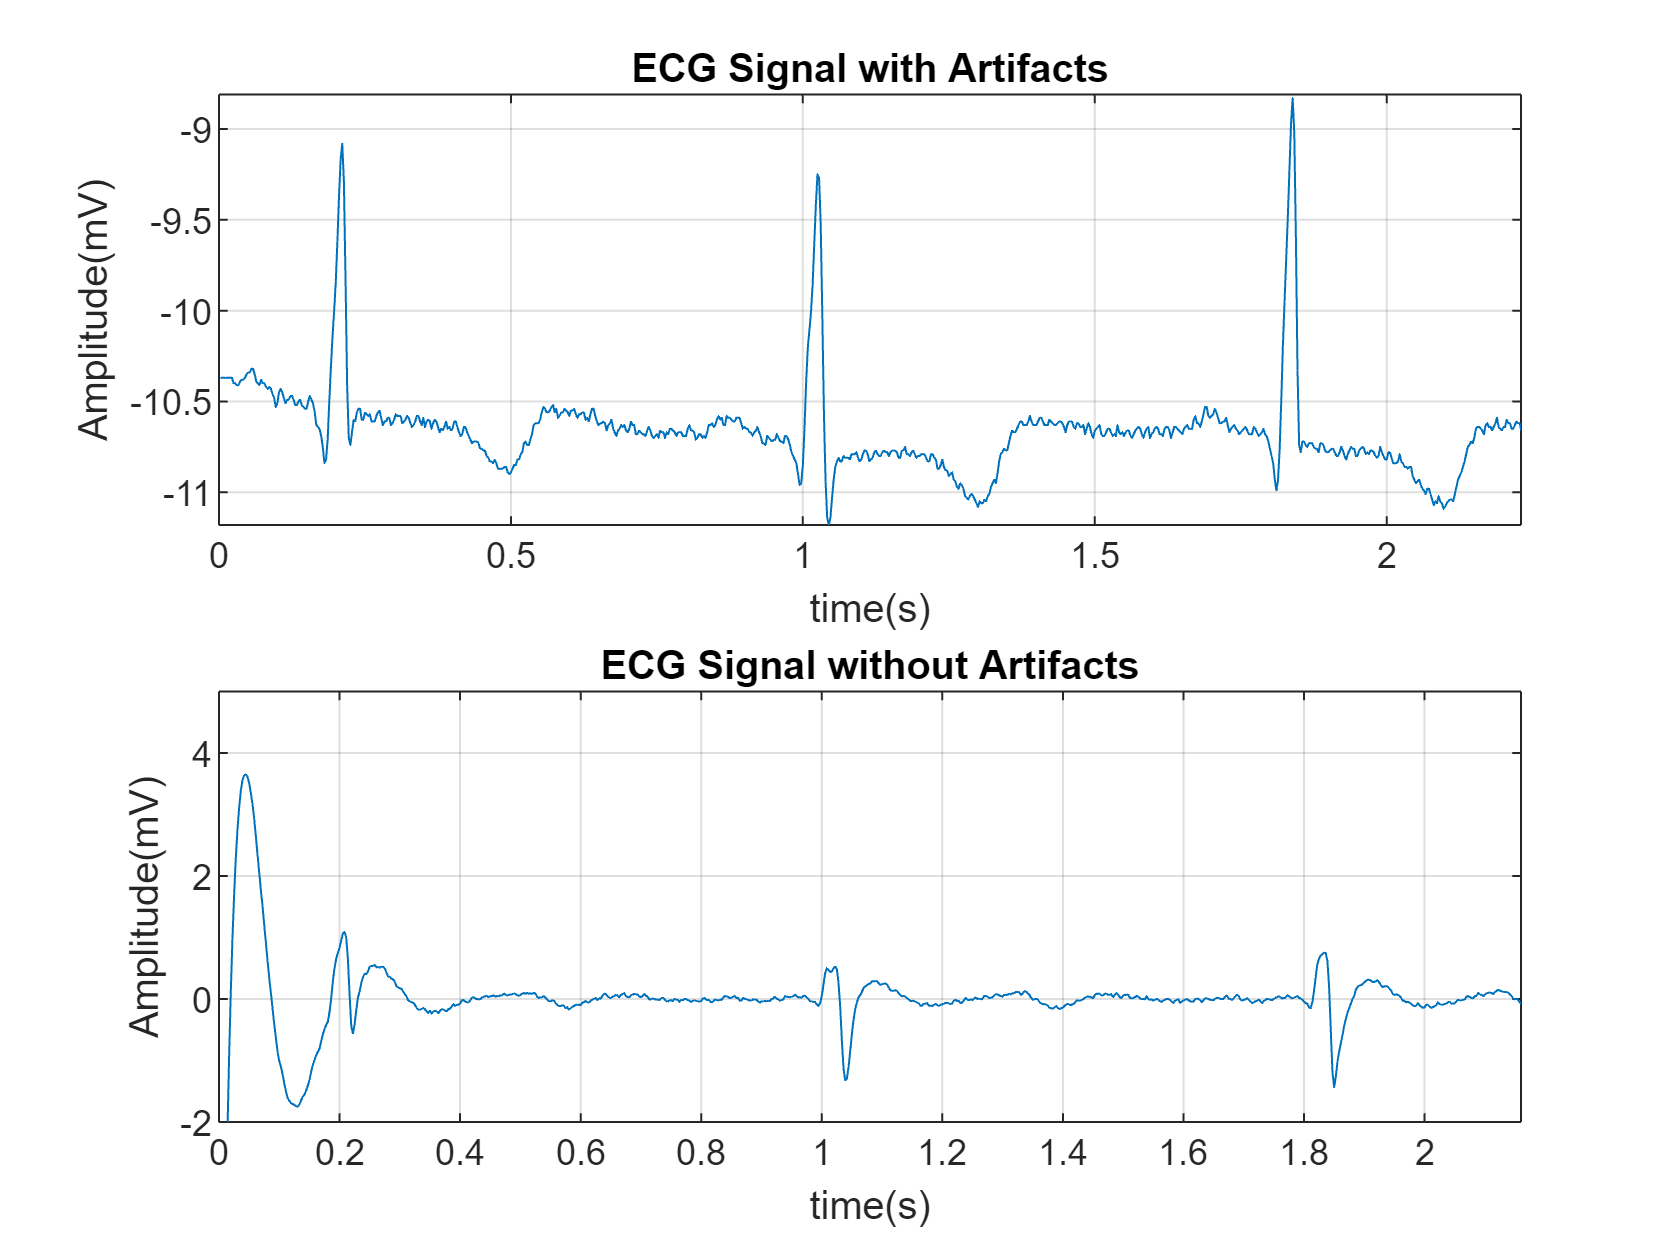

%Reconstructing the signal
ECG_filtered = filter(b,a,ECGsignal_original);
subplot(211)
plot(t,ECGsignal_original)
title('ECG Signal with Artifacts')
xlabel('time(s)')
ylabel('Amplitude(mV)')
xlim([0.00 2.23])
ylim([-11.18 -8.81])
grid on
subplot(212)
plot(t,ECG_filtered)
title('ECG Signal without Artifacts')
xlabel('time(s)')
ylabel('Amplitude(mV)')
xlim([0.00 2.16])
ylim([-2.0 5.0])
grid on